% Train and test all data with one-class SVM classifier

clear;
clc;

data =table();
featureTrain = table();
featureTest = table();

for ii= 1:7
    % number = num2str(ii);
    fname= sprintf("Perturb_Data New/CleanCh%dF.mat",ii);
    wname= sprintf("Perturb_Data New/CleanCh%dW.mat",ii);
    f=load(fname);
    w=load(wname);
    
    f=f.dataTable;
    w=w.dataTable;

    data=[f;w];

    features = GenerateTop20Features(data);
    
    rng(0)
    idx = cvpartition(features.label, "HoldOut",0.3);
    featureTrain = [ featureTrain; features(idx.training,:)];
    featureTest =  [ featureTest;  features(idx.test,:)];
end



%separate train data such that, training data only contains working samples
trueAnomaliesTest = featureTest.label;
featureNormal = featureTrain(featureTrain.label == "Working", :);

%fit one class SVM onto the data

% mdlOCSVM = fitcsvm(featureNormal{:,2:end},'label','Standardize',true,'OutlierFraction',0);
 mdlOCSVM = ocsvm(featureNormal{:,2:end}, "ContaminationFraction", 0, "StandardizeData", true, "KernelScale", 3.3);

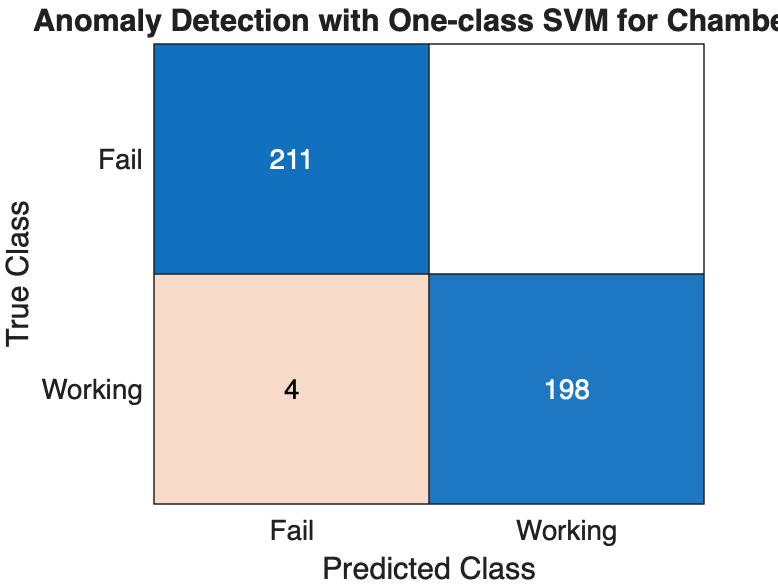

% Validate using the test data
featureTestNoLabels = featureTest(:, 2:end);
isanomalyOCSVM = isanomaly(mdlOCSVM, featureTestNoLabels.Variables, "ScoreThreshold", -0.4);
predOCSVM = categorical(isanomalyOCSVM, [1, 0], ["Fail", "Working"]);

acc = numel(find(predOCSVM == trueAnomaliesTest))/numel(predOCSVM)*100;

% trueAnomaliesTest = renamecats(trueAnomaliesTest,["Working","Fail"], ["Normal","Fail"]);
figure;
title1= sprintf("Anomaly Detection with One-class SVM for Chamber %d", ii);
confusionchart(trueAnomaliesTest, predOCSVM, Title=title1);


[confMat, order] = confusionmat(trueAnomaliesTest, predOCSVM);
TP = confMat(2,2);
FP = confMat(1,2);
FN = confMat(2,1);

precision = TP / (TP + FP);
recall = TP / (TP + FN);
F1 = 2 * (precision * recall) / (precision + recall);

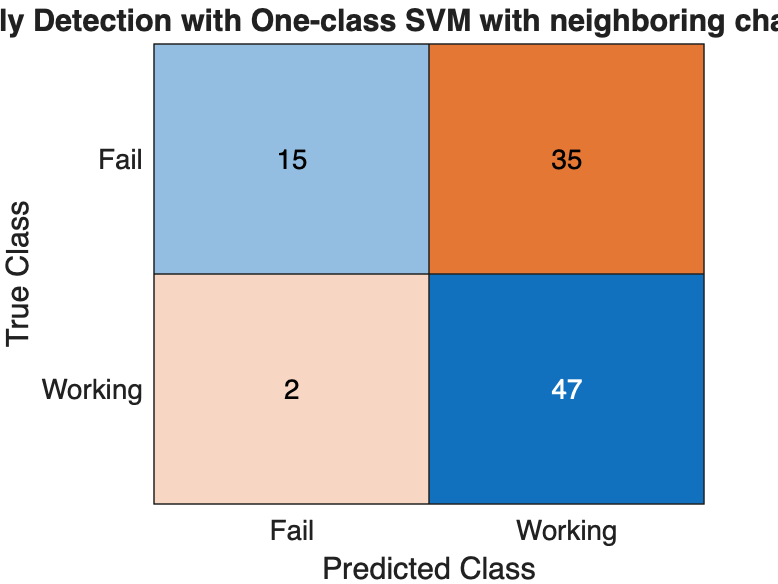

% OCSVM testing with MC data
%test against multi-chamber data
mc_fail = load("Perturb_Data New/F4_35d.mat");
mc_work = load("Perturb_Data New/W4_35d.mat");

mcf = mc_fail.dataTable;
mcw = mc_work.dataTable;

dat_mc = [mcf;mcw];

featmc =GenerateTop20Features(dat_mc);

trueAnomaliesTestmc = featmc.label;

featureTestNoLabelsmc = featmc(:, 2:end);
isanomalyOCSVMmc = isanomaly(mdlOCSVM, featureTestNoLabelsmc.Variables, "ScoreThreshold", 0.06);
predOCSVMmc = categorical(isanomalyOCSVMmc, [1, 0], ["Fail", "Working"]);


figure;
title2= sprintf("Anomaly Detection with One-class SVM with neighboring chamber failure");
confusionchart(trueAnomaliesTestmc, predOCSVMmc, Title=title2);

%Implement anomaly detection using isolation forest
[mdlIF,~,scoreTrainIF] = iforest(featureNormal{:,2:end},'ContaminationFraction',0, 'NumLearners', 100, "NumObservationsPerLearner", 10);

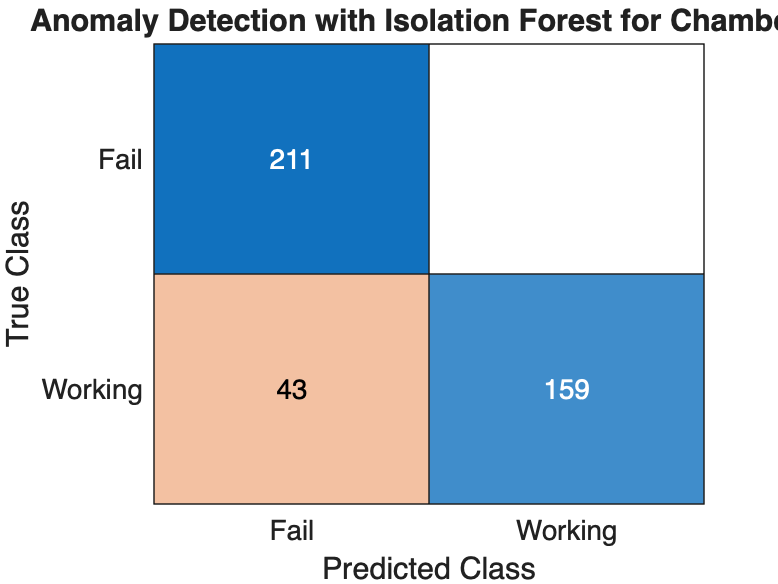

% validate isolation forest model
[isanomalyIF,scoreTestIF] = isanomaly(mdlIF,featureTestNoLabels.Variables, 'ScoreThreshold', 0.535);
predIF = categorical(isanomalyIF, [1, 0], ["Fail", "Working"]);
figure;
title2=sprintf("Anomaly Detection with Isolation Forest for Chamber %d",ii);
confusionchart(trueAnomaliesTest,predIF,Title=title2);